clc; clear; close all;

%% ==========================================================
%  BLOQUE 1: ANÁLISIS SIMBÓLICO: ROBOT CILÍNDRICO (RPP)
%  ==========================================================
disp("=== ANÁLISIS SIMBÓLICO: ROBOT CILÍNDRICO (RPP) ===")

=== ANÁLISIS SIMBÓLICO: ROBOT CILÍNDRICO (RPP) ===



% Variables simbólicas. q1 es rotacional, d2 y d3 son prismáticas.
syms q1 d2 d3 l1 beta1 real 

% --- 1. Eslabón 1 (Revoluta Z) ---
% Rota en Z y sube por el pilar fijo
H1_0_sym = simplify( Hrz(q1) * Htz(l1+beta1) * Htx(0) * round(Hrx(0)) );
disp(">>> Matriz H1_0:"); disp(H1_0_sym);

>>> Matriz H1_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \beta_{1}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- 2. Eslabón 2 (Prismático Z) ---
% Sube en Z y rota 90 grados en Y para que el eje Z apunte hacia el frente (horizontal)
H2_1_sym = simplify( Hrz(0) * Htz(d2) * Htx(0) * round(Hry(90)) );
H2_0_sym = simplify( H1_0_sym * H2_1_sym );
disp(">>> Matriz H2_0:"); disp(H2_0_sym);

>>> Matriz H2_0:


$$\left(\begin{array}{cccc} 0 & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ -1 & 0 & 0 & \beta_{1}+d_{2}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- 3. Eslabón 3 (Prismático Z - Ahora es horizontal) ---
% Se extiende radialmente
H3_2_sym = simplify( Hrz(0) * Htz(d3) * Htx(0) * round(Hrx(0)) );
H3_0_sym = simplify( H2_0_sym * H3_2_sym );
Pf_sym = [H3_0_sym(1,4); H3_0_sym(2,4); H3_0_sym(3,4)];
disp(">>> Matriz Final H3_0:"); disp(H3_0_sym);

>>> Matriz Final H3_0:


$$\left(\begin{array}{cccc} 0 & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & d_{3}\,\cos\left(q_{1}\right)\\ 0 & \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & d_{3}\,\sin\left(q_{1}\right)\\ -1 & 0 & 0 & \beta_{1}+d_{2}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- Cinemática Diferencial ---
disp("--- CINEMÁTICA DIFERENCIAL ---")

--- CINEMÁTICA DIFERENCIAL ---


J_sym = simplify(jacobian(Pf_sym, [q1, d2, d3]));
Det_J_sym = simplify(det(J_sym));
disp(">>> Matriz Jacobiana (3x3):"); disp(J_sym);

>>> Matriz Jacobiana (3x3):


$$\left(\begin{array}{ccc} -d_{3}\,\sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right)\\ d_{3}\,\cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right)\\ 0 & 1 & 0 \end{array}\right)$$

disp(">>> Determinante de la Jacobiana:"); disp(Det_J_sym);

>>> Determinante de la Jacobiana:


$$d_{3}$$



%% ==========================================================
%  BLOQUE 2: ROBOT 1 (Configuración Estándar)
%  ==========================================================
disp("=== ROBOT 1: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 1: EVALUACIÓN Y GRÁFICAS ===


% Parámetros físicos
r1_l1 = 0.4; r1_b1 = 0.1; 
r1_q1 = deg2rad(45); r1_d2 = 0.3; r1_d3 = 0.5; % d2 elevación, d3 extensión

sym_vars = [q1, d2, d3, l1, beta1];
vals_R1  = [r1_q1, r1_d2, r1_d3, r1_l1, r1_b1];

% Evaluaciones Numéricas
H1_R1 = double(subs(H1_0_sym, sym_vars, vals_R1)); S1_R1 = H1_R1(1:3, 4);
H2_R1 = double(subs(H2_0_sym, sym_vars, vals_R1)); S2_R1 = H2_R1(1:3, 4);
H3_R1 = double(subs(H3_0_sym, sym_vars, vals_R1)); Pf_R1 = H3_R1(1:3, 4);

disp("Punto Final Pf_R1 (X, Y, Z):"); disp(Pf_R1');

Punto Final Pf_R1 (X, Y, Z):
    0.3536    0.3536    0.8000



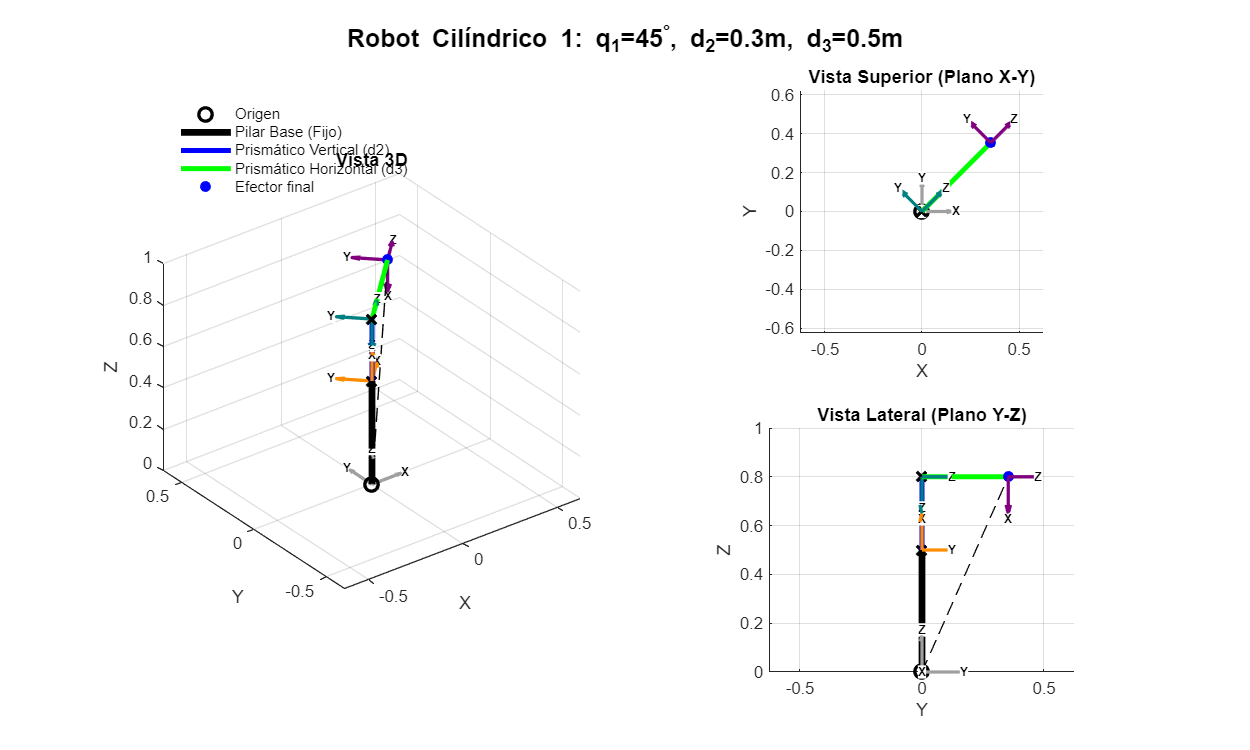


R_max1 = r1_d3;             % Alcance radial máximo
H_max1 = r1_l1+r1_b1+r1_d2; % Altura máxima
figure('Name', 'Robot Cilíndrico 1', 'Position', [50, 100, 1000, 600]);
sgtitle(['Robot Cilíndrico 1: q_1=' num2str(rad2deg(r1_q1)) '^\circ, d_2=' num2str(r1_d2) 'm, d_3=' num2str(r1_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg = plotRobotCilindrico(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, R_max1, H_max1);
view(3); title('Vista 3D');
legend([h_leg.orig, h_leg.pilar, h_leg.d2, h_leg.d3, h_leg.pf], ...
       {'Origen', 'Pilar Base (Fijo)', 'Prismático Vertical (d2)', 'Prismático Horizontal (d3)', 'Efector final'}, ...
       'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotCilindrico(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, R_max1, H_max1);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotCilindrico(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, R_max1, H_max1);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


[qi1, di2, di3] = cinv_Cilindrico(r1_l1, r1_b1, Pf_R1(1), Pf_R1(2), Pf_R1(3));
disp("Cinemática Inversa R1 (q1, d2, d3):"); disp([qi1, di2, di3]);

Cinemática Inversa R1 (q1, d2, d3):
   45.0000    0.3000    0.5000





%% ==========================================================
%  BLOQUE 3: ROBOT 2 (Mucha elevación, poca extensión)
%  ==========================================================
disp("=== ROBOT 2: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 2: EVALUACIÓN Y GRÁFICAS ===


r2_l1 = 0.5; r2_b1 = 0.05; 
r2_q1 = deg2rad(135); r2_d2 = 0.6; r2_d3 = 0.2; 

vals_R2  = [r2_q1, r2_d2, r2_d3, r2_l1, r2_b1];

H1_R2 = double(subs(H1_0_sym, sym_vars, vals_R2)); S1_R2 = H1_R2(1:3, 4);
H2_R2 = double(subs(H2_0_sym, sym_vars, vals_R2)); S2_R2 = H2_R2(1:3, 4);
H3_R2 = double(subs(H3_0_sym, sym_vars, vals_R2)); Pf_R2 = H3_R2(1:3, 4);

disp("Punto Final Pf_R2 (X, Y, Z):"); disp(Pf_R2');

Punto Final Pf_R2 (X, Y, Z):
   -0.1414    0.1414    1.1500



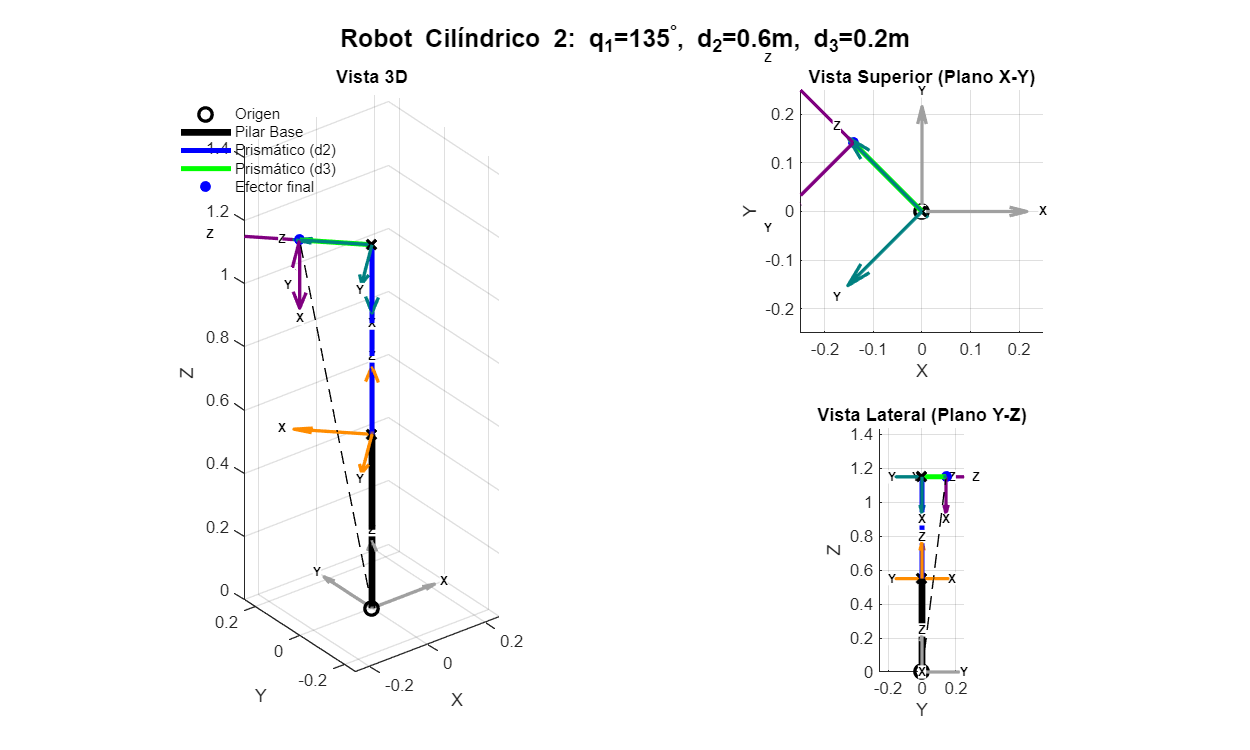


R_max2 = r2_d3; 
H_max2 = r2_l1+r2_b1+r2_d2; 
figure('Name', 'Robot Cilíndrico 2', 'Position', [100, 150, 1000, 600]);
sgtitle(['Robot Cilíndrico 2: q_1=' num2str(rad2deg(r2_q1)) '^\circ, d_2=' num2str(r2_d2) 'm, d_3=' num2str(r2_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg2 = plotRobotCilindrico(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, R_max2, H_max2);
view(3); title('Vista 3D');
legend([h_leg2.orig, h_leg2.pilar, h_leg2.d2, h_leg2.d3, h_leg2.pf], ...
       {'Origen', 'Pilar Base', 'Prismático (d2)', 'Prismático (d3)', 'Efector final'}, 'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotCilindrico(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, R_max2, H_max2);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotCilindrico(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, R_max2, H_max2);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


[qi1, di2, di3] = cinv_Cilindrico(r2_l1, r2_b1, Pf_R2(1), Pf_R2(2), Pf_R2(3));
disp("Cinemática Inversa R2 (q1, d2, d3):"); disp([qi1, di2, di3]);

Cinemática Inversa R2 (q1, d2, d3):
  135.0000    0.6000    0.2000





%% ==========================================================
%  BLOQUE 4: ROBOT 3 (Cuadrante negativo)
%  ==========================================================
disp("=== ROBOT 3: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 3: EVALUACIÓN Y GRÁFICAS ===


r3_l1 = 0.3; r3_b1 = 0.1; 
r3_q1 = deg2rad(-60); r3_d2 = 0.1; r3_d3 = 0.8; 

vals_R3  = [r3_q1, r3_d2, r3_d3, r3_l1, r3_b1];

H1_R3 = double(subs(H1_0_sym, sym_vars, vals_R3)); S1_R3 = H1_R3(1:3, 4);
H2_R3 = double(subs(H2_0_sym, sym_vars, vals_R3)); S2_R3 = H2_R3(1:3, 4);
H3_R3 = double(subs(H3_0_sym, sym_vars, vals_R3)); Pf_R3 = H3_R3(1:3, 4);

disp("Punto Final Pf_R3 (X, Y, Z):"); disp(Pf_R3');

Punto Final Pf_R3 (X, Y, Z):
    0.4000   -0.6928    0.5000



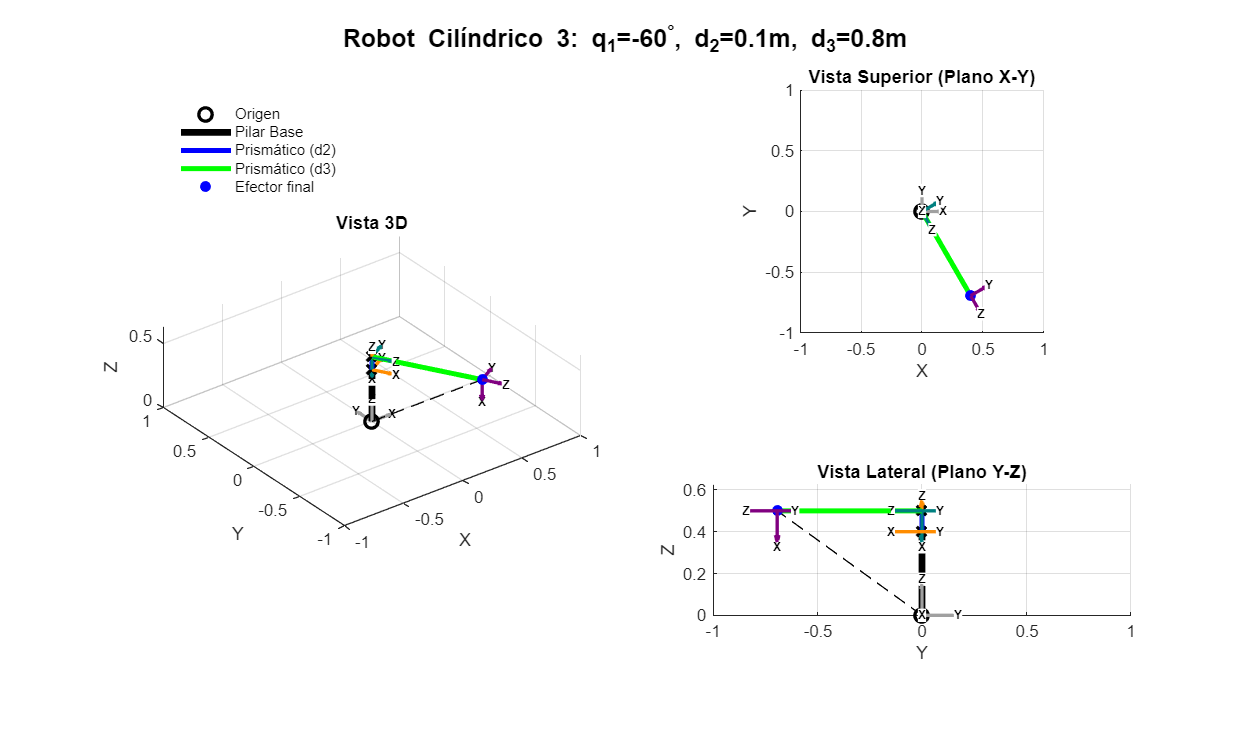


R_max3 = r3_d3; 
H_max3 = r3_l1+r3_b1+r3_d2;
figure('Name', 'Robot Cilíndrico 3', 'Position', [150, 200, 1000, 600]);
sgtitle(['Robot Cilíndrico 3: q_1=' num2str(rad2deg(r3_q1)) '^\circ, d_2=' num2str(r3_d2) 'm, d_3=' num2str(r3_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg3 = plotRobotCilindrico(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, R_max3, H_max3);
view(3); title('Vista 3D');
legend([h_leg3.orig, h_leg3.pilar, h_leg3.d2, h_leg3.d3, h_leg3.pf], ...
       {'Origen', 'Pilar Base', 'Prismático (d2)', 'Prismático (d3)', 'Efector final'}, 'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotCilindrico(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, R_max3, H_max3);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotCilindrico(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, R_max3, H_max3);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


[qi1, di2, di3] = cinv_Cilindrico(r3_l1, r3_b1, Pf_R3(1), Pf_R3(2), Pf_R3(3));
disp("Cinemática Inversa R3 (q1, d2, d3):"); disp([qi1, di2, di3]);

Cinemática Inversa R3 (q1, d2, d3):
  -60.0000    0.1000    0.8000





%% ==========================================================
%  FUNCIONES LOCALES
%  ==========================================================
function h = plotRobotCilindrico(S1, S2, Pf, H1, H2, H3, max_radius, max_height)
    hold on; grid on; axis equal;
    
    % Origen
    h.orig = plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Pilar Base (Cuerpo Fijo)
    h.pilar = plot3([0, S1(1)], [0, S1(2)], [0, S1(3)], 'k', 'LineWidth', 4);
    plot3(S1(1), S1(2), S1(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Eslabón Prismático Vertical (d2)
    h.d2 = plot3([S1(1), S2(1)], [S1(2), S2(2)], [S1(3), S2(3)], 'b', 'LineWidth', 3);
    plot3(S2(1), S2(2), S2(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Eslabón Prismático Horizontal (d3)
    h.d3 = plot3([S2(1), Pf(1)], [S2(2), Pf(2)], [S2(3), Pf(3)], 'g', 'LineWidth', 3); 
    h.pf = plot3(Pf(1), Pf(2), Pf(3), 'bo', 'MarkerFaceColor', 'b');
    
    % Línea guía al suelo
    plot3([0, Pf(1)], [0, Pf(2)], [0, Pf(3)], 'k--'); 
    
    % Límites dinámicos (Cilindro virtual)
    lim_xy = max_radius * 1.25; 
    if lim_xy == 0, lim_xy = 0.5; end % Evitar errores si d3 es 0
    lim_z  = max_height * 1.25; 
    xlim([-lim_xy, lim_xy]); ylim([-lim_xy, lim_xy]); zlim([0, lim_z]); 
    
    % Sistemas de Referencia
    scale = max(lim_xy, lim_z) * 0.15; 
    q0 = drawFrame(eye(4), scale); q0.Color = '#A0A0A0';
    q1 = drawFrame(H1, scale);     q1.Color = '#FF8C00';
    q2 = drawFrame(H2, scale);     q2.Color = '#008080';
    q3 = drawFrame(H3, scale);     q3.Color = '#800080';
    
    xlabel('X'); ylabel('Y'); zlabel('Z');
end